# Channel Matched Filter Precoder

% Downlink with 1D Antenna Formation
% Different AOA for Users

## Global Parameter

clc;
clearvars;

% Number of Antennas and Users
M = 50;
K = 19;

% Channel Length
L = 4;

% Block Length
T = 100;

% Monte-Carlo Parameter
Ni = 50;

% Plot Points
Pi = 500;

% Time Shield
TS = L + 1;

% Range of Power
r = linspace(0.01, 10, Pi);
e = mag2db(r / 2);

% Channel PDP
u = (0 : K - 1) / 5; % Phase
for l = 1 : L
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : L - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end

% Besse Correlation Pattern
di = 0.5;% Distance Between Adjacent Antennas
etta = 10; % Width of the AOA
mu = linspace(-pi / 2, pi / 2, K); % Mean Direction of the AOA
for k = 1 : K
    A1 = di * (0 : M - 1);
    arg = etta ^ 2 - 4 * (pi ^ 2) * (A1) .^ 2 + 4i * pi * etta * sin(mu(k)) .* A1;
    A2 = besseli(0, sqrt(arg)) ./ besseli(0, etta);
    A(:, :, k) = toeplitz(A2);
end

## System Model

% Channel in Time
for n = 1 : Ni
    si(:, :, n) = (sqrt(0.5)) * (randn(K, T) + 1i * randn(K, T));
    zi(:, :, n) = (sqrt(0.5)) * (randn(K, T) + 1i * randn(K, T));
    
    for l = 1 : L
        for k = 1 : K
            H1 = ((A(:, :, k)) ^ (0.5)) * (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
            D1 = D(:, :, l) .^ (0.5);
            Hl(:, :, k, l, n) = H1 * D1;
        end
    end
	Wl(:, :, :, :, n) = Hl(:, :, :, :, n);
    for k = 1 : K
        [AW(k, n)] = Signal_Power(L, Wl(:, :, k, :, n));
    end
    
    % Composite Effect Matrix
    for l = 1 : L
        for k = 1 : K
            El(:, :, k, l, n) = (Hl(:, :, k, l, n))' * (Wl(:, :, k, l, n));
        end
    end
end
    
% Normalization Factors
A_W = mean(1 ./ mean(AW, 2));

% Desired Signal
for n = 1 : Ni
    for k = 1 : K
        for l = 1 : L
            gk(k, :, n, l) = A_W * mean(El(k, k, k, l, :), 5) * si(k, :, n);
        end
    end
end
gi = sum(gk, 4);

% Transmit Signal
for n = 1 : Ni
    for l = 1 : L
        for k = 1 : K
            for i = 1 : T - TS
                xl(:, k, i, n, l) = A_W * (Wl(:, :, k, l, n)) * si(:, i + l, n);
            end
        end
    end
end
xi = sum(xl, 5);

% Channel Output Signal
for n = 1 : Ni
    for l = 1 : L
        for k = 1 : K
            for i = TS : T - TS
                yl(:, i, n, l)=(Hl(:, :, k, l, n))' * xi(:, k, i - l, n);
            end
        end
    end
end
yi = sum(yl, 4);

% Effective Noise
ni(:, TS : T - TS, :) = yi(:, TS : T - TS, :) - gi(:, TS : T - TS, :);

% Capacity
El_sum = A_W * sum(mean(El, 5), 4);
for n = 1 : Ni
    for k = 1 : K
        Sk(k, :, n) = abs(El_sum(k, k, k)) ^ 2 * r(:);
        Ck(k, :, n) = log2(1 + (Sk(k, :, n)));
    end
end
Ct = sum(mean(Ck, 3) , 1);

% Achievable Rate
for n = 1 : Ni
    for k = 1 : K
        Sn(k, :, n) = var(ni(k, :, n), 0, 2) * r(:) + 1;
        SNR(k, :, n) = (Sk(k, :, n)) ./ (Sn(k, :, n));
        Rk(k, :, n) = log2(1 + (SNR(k, :, n)));
    end
end
Rt = sum(mean(Rk, 3), 1);

## Theoretical Result

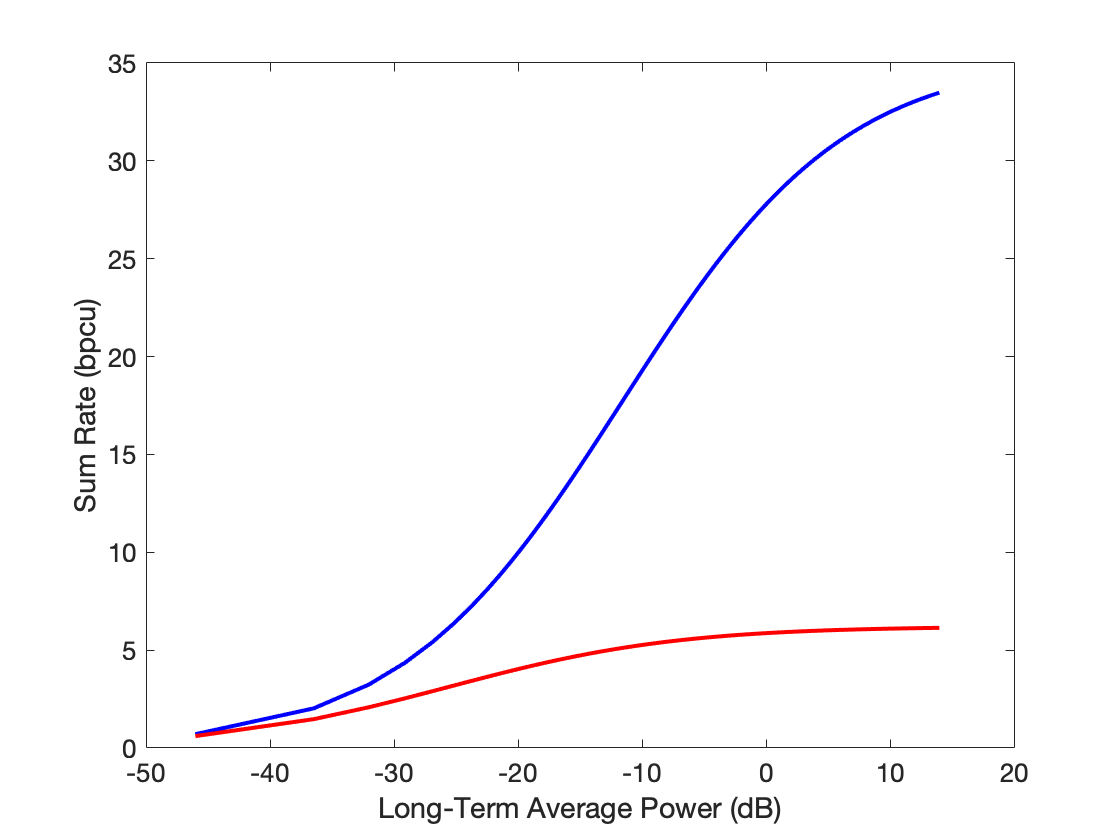

Pth=(M/K)*r;
Nth=r+1;
SNRth=Pth./Nth;
Cth=K*log2(1+Pth);
Rth=K*log2(1+SNRth);

% Ploting Part
%figure;
%plot(e, Ct, 'b', e, Rt, 'r');
%title('Simulations Result', 'fontsize', 15);
%xlabel('Long-Term Average Power (dB)', 'fontsize', 15);
%ylabel('Sum Rate (bpcu)', 'fontsize', 15);
%set(gca, 'fontsize', 13);
%set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);

figure;
index = [1, 2, 5, 13, 41, 127, 400];

plot(e, Rth, 'b', e, Rt, 'r');
title('', 'fontsize', 15);
xlabel('Long-Term Average Power (dB)', 'fontsize', 15);
ylabel('Sum Rate (bpcu)', 'fontsize', 15);
set(gca, 'fontsize', 13);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);